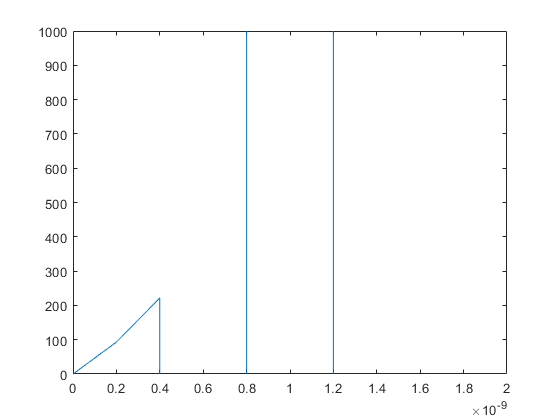

Vg(1:250) = -3;
Vg(251:10002) = 6;
Vghigh = 6;
Vglow = -3;
Ciss = 242e-12;
Ron = 20;
time_step = 2E-10;
index_max = 100;
time = time_step*(0:index_max);
Vgs = (Vghigh-Vglow)*(1-exp(-time./(Ron*Ciss))) + Vglow;


p1 = -3.873;
p2 = 53.49;
p3 = -73.09;

Vo = 400;
R = Vo./(p1.*Vgs.^2 + p2.*Vgs + p3);
C = 220e-9;
L = 0.86e-9;


sum_ic = 0;
ic(1) = 0;
for i=1:index_max
    alpha = Vo - 1/C*sum_ic;
    beta = ic(i)*R(i);
    if (beta > 400)
        beta = 400;
    end
    ic(i+1) = (alpha-beta)*time_step/L + ic(i);
    sum_ic = sum_ic + ic(i);    
end

figure
plot(time,ic)
ylim([0 1000])
xlim([0 2E-9])